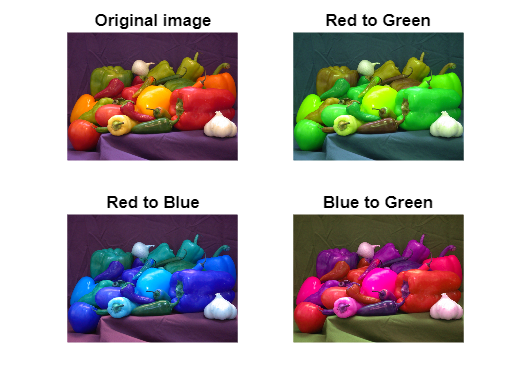

originalRGB = imread('peppers.png');
figure;
subplot(221);
imshow(originalRGB);
title("Original image");

% swap red to green
red = originalRGB(:,:,1);
g(:,:,1) = originalRGB(:,:,2);
g(:,:,2) = red;
g(:,:,3) = originalRGB(:,:,3);
subplot(222);
imshow(g);
title("Red to Green");

% swap red to blue
blue = originalRGB(:,:,3);
r(:,:,1) = blue;
r(:,:,2) = originalRGB(:,:,2);
r(:,:,3) = originalRGB(:,:,1);
subplot(223);
imshow(r);
title("Red to Blue");

% swap blue to green
green = originalRGB(:,:,2);
b(:,:,1) = originalRGB(:,:,1);
b(:,:,2) = originalRGB(:,:,3);
b(:,:,3) = green;
subplot(224);
imshow(b);
title("Blue to Green");

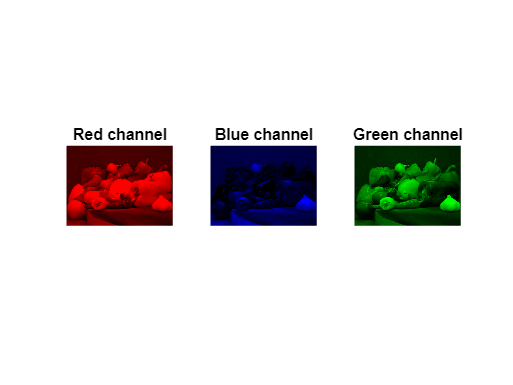

% red channel
figure;

red(:,:,1) = originalRGB(:,:,1);
red(:,:,2) = 0;
red(:,:,3) = 0;

subplot(131);
imshow(red);
title("Red channel");

% blue
blue(:,:,1) = 0;
blue(:,:,2) = 0;
blue(:,:,3) = originalRGB(:,:,3);

subplot(132);
imshow(blue);
title("Blue channel");

% green
green(:,:,1) = 0;
green(:,:,2) = originalRGB(:,:,2);
green(:,:,3) = 0;

subplot(133);
imshow(green);
title("Green channel");

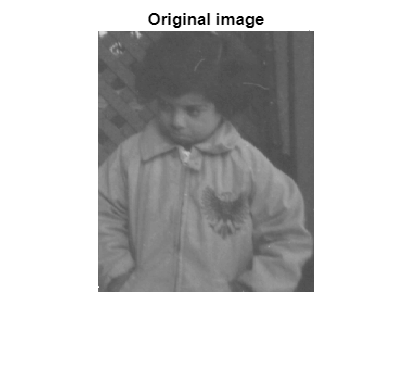

% 5
figure;
srcImage = imread("pout.tif");
imshow(flippedImage);
title("Original image");

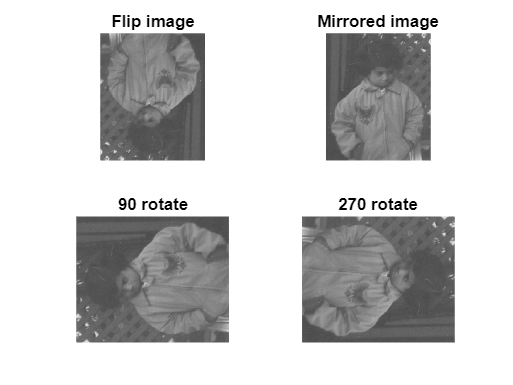


% flipped
figure;
I1 = flip(srcImage, 1);
subplot(221);
imshow(I1);
title("Flip image");

% mirror
I2 = flip(srcImage, 2);
subplot(222);
imshow(I2);
title("Mirrored image");

% 90
I3 = imrotate(srcImage, 90);
subplot(223);
imshow(I3);
title("90 rotate");

% 270
I4 = imrotate(srcImage, 270);
subplot(224);
imshow(I4);
title("270 rotate");

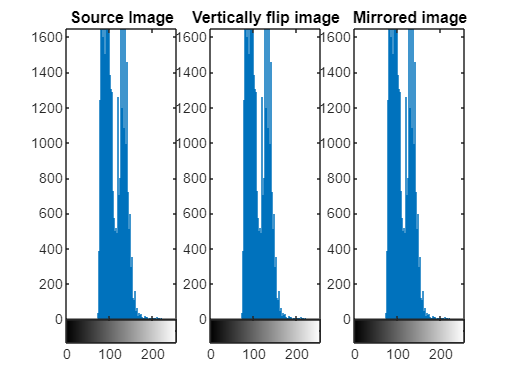


% histogram
figure;
subplot(131);
imhist(srcImage);
title("Source Image");

subplot(132);
imhist(I1);
title("Vertically flip image");

subplot(133);
imhist(I2);
title("Mirrored image");


% they all look the same SAME FUCKING IMAGE BRO JUST FLIPPING

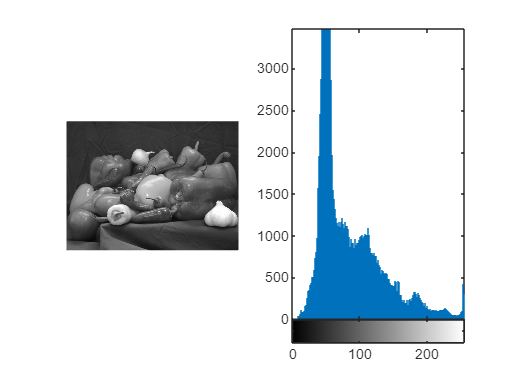

% convert grayscale
figure;
gsoriginalRGB = rgb2gray(originalRGB);
subplot(121);
imshow(gsoriginalRGB);

% plot histogram
subplot(122);
imhist(gsoriginalRGB);

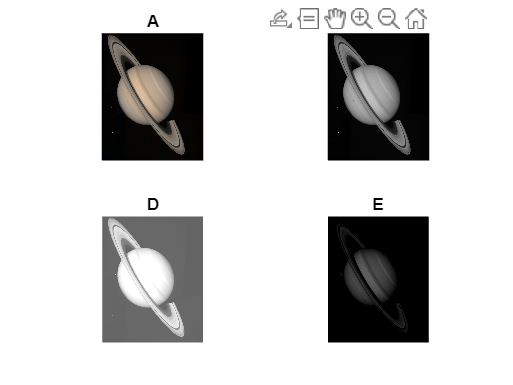

% saturn
A = imread('saturn.png');
B = rgb2gray(A);
C = uint16(B);

% operation
D = imadd(C, 100);
E= imsubtract(C, 100);

% change back to 8
Df = uint8(D);
Ef = uint8(E);

figure;
subplot(221);
imshow(A);
title("A");

subplot(222);
imshow(B);
title("B");

subplot(223);
imshow(Df);
title("D");

subplot(224);
imshow(Ef);
title("E");